# **Lab 3 - T1 2020 (Question 2)**

***by Jason Ha***

## Question 2

### Part (a)

We are given the following fifth order filter, $H\left(z\right)$:


$$H\left(z\right)=\left(\frac{z-{r_{\;} }_1 }{z}\right)\left(\frac{z^2 -2r_2 \cos \theta_2 +r_2^2 }{z^2 }\right)\left(\frac{z^2 -2r_3 \cos \theta_2 +r_3^2 }{z^2 }\right)\;$$


We can use polynomial multiplication to conveniently get the coefficients of the numerator polynomial which are the filter taps for $H\left(z\right)$. We can perform this using *conv* in the code cell below:

% Initialise the numerator polynomials for each first/second-order section
Q0 = [1 exp(-1/8)];
Q1 = [1, 0.556, 0.81];
Q2 = [1, 1.604, 0.81];

% Convolve each array in twos:
tmp = conv(Q0, Q1);
expanded_num = conv(tmp, Q2);

% For convenient syntax, let E be expanded_num - Row vector:
E = expanded_num;

*expanded_num* is the impulse of the filter. The fact that the filter is an all-zero filter justifies its finite length and hence makes this an FIR filter.

### Part (b)

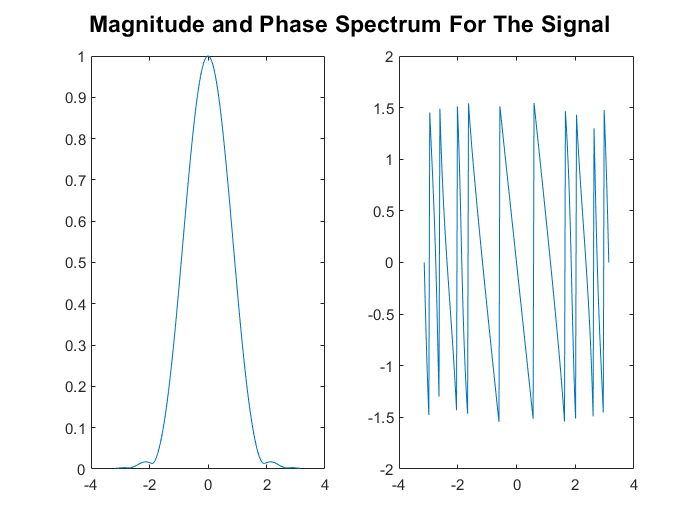

% Generate a vector of complex exponentials - Column vector:
omega = -pi:pi/100:pi;
w = transpose(exp(-1i*omega));

% For each element in w, multiply with the coefficients of the transfer
% function. This is the equivalent of substitution. Append the result to
% another output array:
Y = polyval(E, w);

% Magnitude spectrum is the absolute value of the vector, y. Normalise the
% frequency response:
mag = abs(Y);
mag = mag / max(mag);

% Phase spectrum is the arctan of the ratio of the imaginary to the real
% component:
phase = atan(imag(Y)./real(Y));

% Plot the magnitude and phase spectrum on a figure as subplots:
figure
subplot(1,2,1)
plot(omega, mag)
subplot(1,2,2)
plot(omega, phase)
sgtitle("Magnitude and Phase Spectrum For The Signal", 'fontweight', 'bold')

### Part (c)

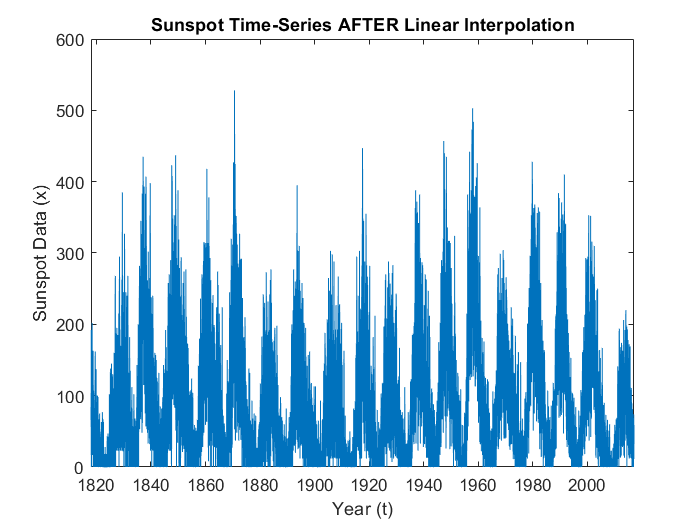

% Use the function 'readtable' to read the CSV file into the workspace
% Assign the loaded dataset to the variable 'raw'
raw = readtable("sunspot_data.csv");

% Extracting the 4th and 5th columns and renaming them to t and x
% respectively
t = table2array(raw(:, 4));
x = table2array(raw(:, 5));
years = table2array(raw(:,1));

% Assign NaN values to any entry in x whose value is -1.
x(x == -1) = NaN;

% Interpolating missing values in the data. TF is a boolean array
% indicating the indices that have been populated by interpolation.
[xn,TF] = fillmissing(x, 'nearest', 'SamplePoints', t);

% Plot the sunspot data so far.
figure
plot(t, xn)
title("Sunspot Time-Series AFTER Linear Interpolation")
xlabel("Year (t)")
ylabel("Sunspot Data (x)")
xlim([min(t), max(t)])

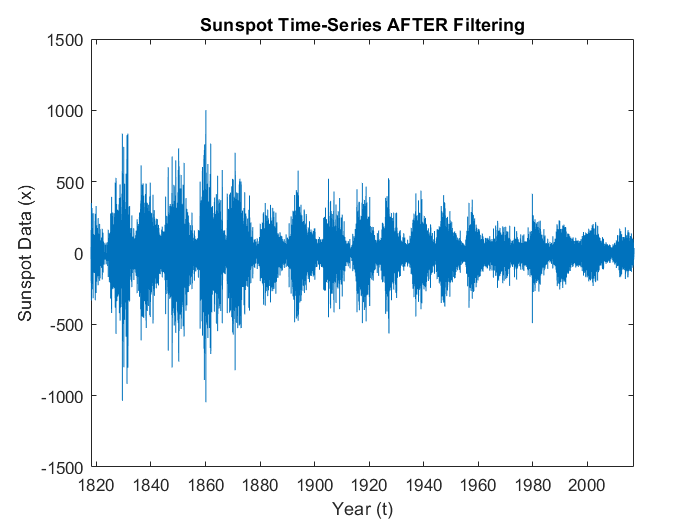


% Applying the filter, take the inverse FFT of the filter's frequency
% response (as a complex vector)
y = ifft(Y, 'symmetric');

% Apply the filter's impulse response to the data:
xn_f = filter(y,1,xn);

figure
plot(t, xn_f)
title("Sunspot Time-Series AFTER Filtering")
xlabel("Year (t)")
ylabel("Sunspot Data (x)")
xlim([min(t), max(t)])